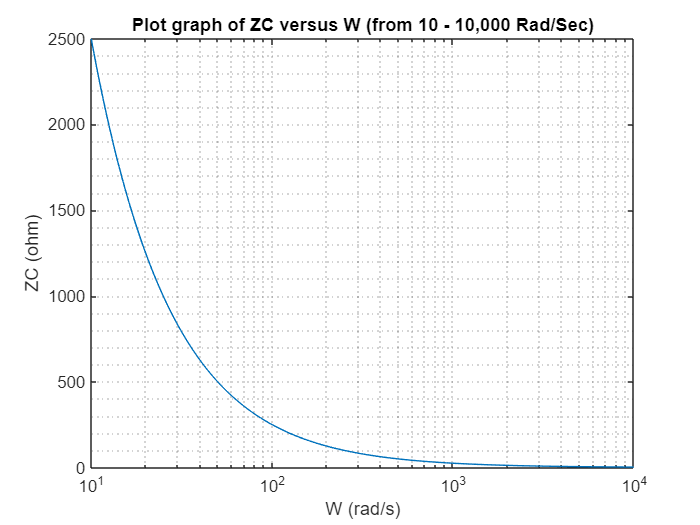

clc
clear
W = logspace(1 , 4 , 1000); % W = 10-1000 Rad/Sec
Vs = 12;            % Voltage
R = 100;                    % Resistor
L = 100e-3;                 % Inductor
C = 40e-6;                  % Capacitor

% init cal value
Zr = R;                     % ZR
Zl = 1j.*W.*L;              % ZL
Zc = -1j./(W.*C);         % ZC
Zt = Zr + Zl + Zc;          % ZT(total)

% plot Zc vs W
figure(1)
abs_Zc = abs(Zc);
semilogx(W,abs_Zc);
xlabel("W (rad/s)")
ylabel("ZC (ohm)")
title("Plot graph of ZC versus W (from 10 - 10,000 Rad/Sec)")
grid minor

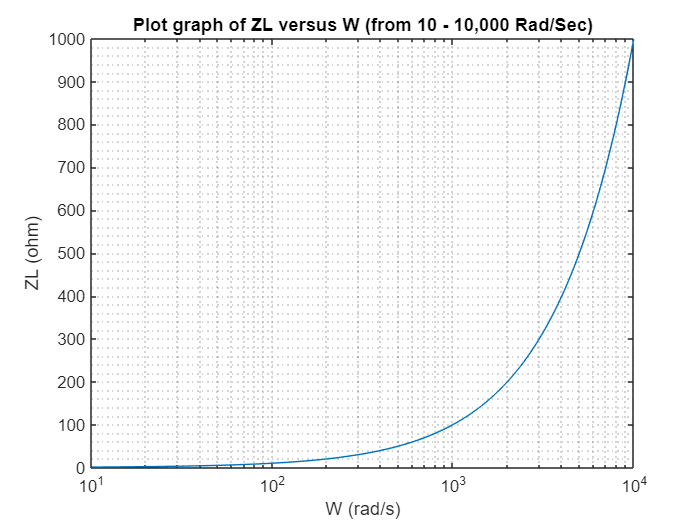


% plot Zl vs W
figure(2)
abs_Zl = abs(Zl);
semilogx(W,abs_Zl)
xlabel("W (rad/s)")
ylabel("ZL (ohm)")
title("Plot graph of ZL versus W (from 10 - 10,000 Rad/Sec)")
grid minor

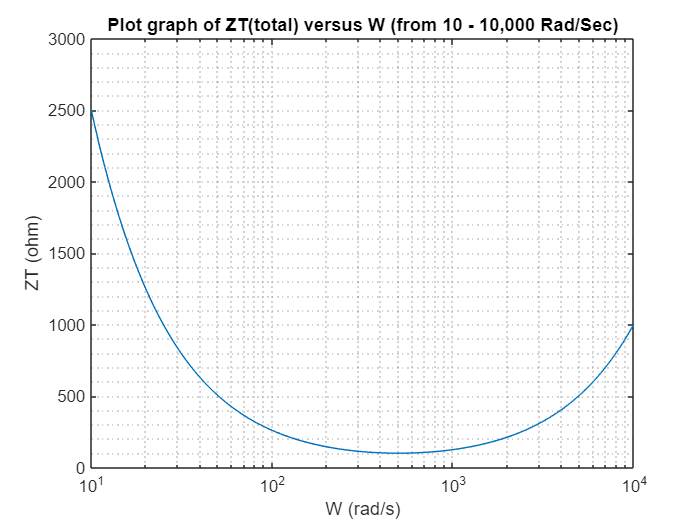


% plot ZT vs W
figure(3)
abs_Zt = abs(Zt);
semilogx(W,abs_Zt)
xlabel("W (rad/s)")
ylabel("ZT (ohm)")
title("Plot graph of ZT(total) versus W (from 10 - 10,000 Rad/Sec)")
grid minor

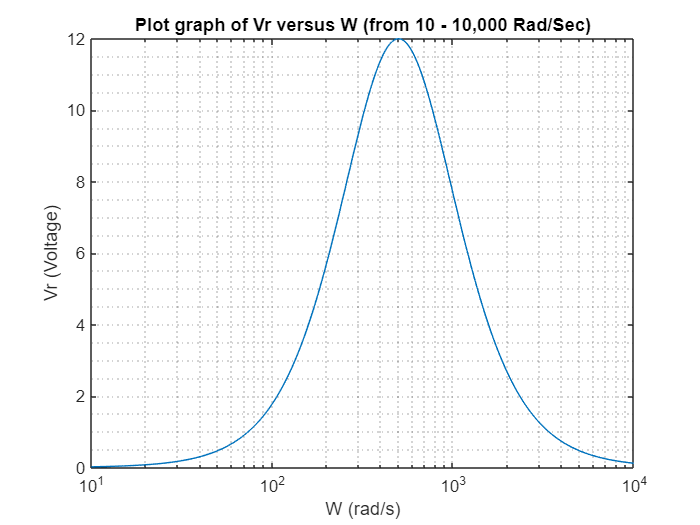


%cal current
i = Vs./Zt;

% plot Vr vs W
figure(4)
Vr = i*Zr;
semilogx(W,real(Vr))
xlabel("W (rad/s)")
ylabel("Vr (Voltage)")
title("Plot graph of Vr versus W (from 10 - 10,000 Rad/Sec)")
grid minor

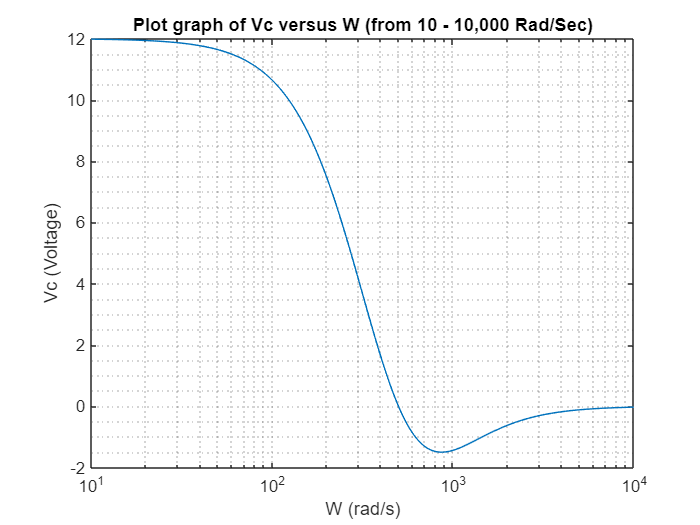


% plot Vc vs W
figure(5)
Vc = i.*Zc;
semilogx(W,real(Vc))
xlabel("W (rad/s)")
ylabel("Vc (Voltage)")
title("Plot graph of Vc versus W (from 10 - 10,000 Rad/Sec)")
grid minor

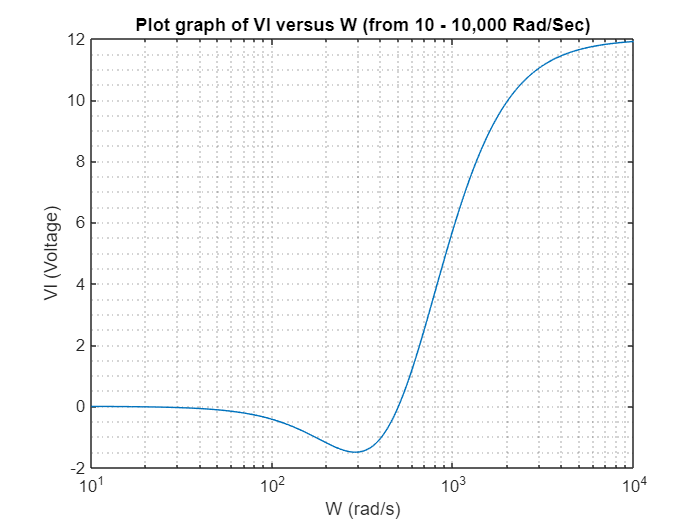


% plot Vc vs W
figure(5)
Vl = i.*Zl;
semilogx(W,real(Vl))
xlabel("W (rad/s)")
ylabel("Vl (Voltage)")
title("Plot graph of Vl versus W (from 10 - 10,000 Rad/Sec)")
grid minor

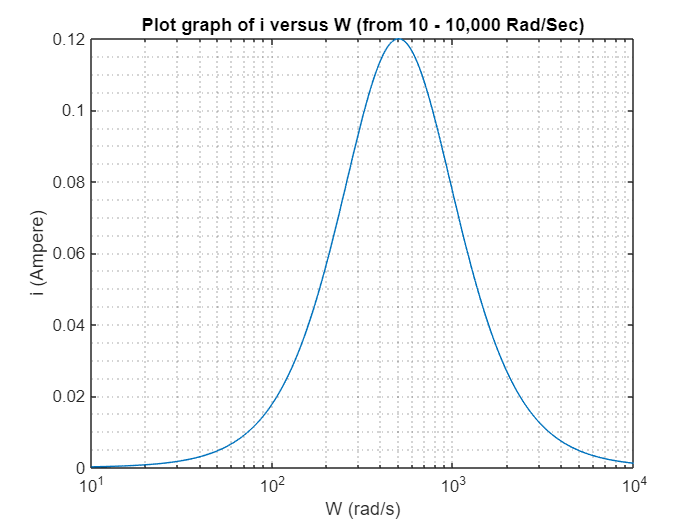


% plot i vs W 
figure(6)
semilogx(W,real(i))
xlabel("W (rad/s)")
ylabel("i (Ampere)")
title("Plot graph of i versus W (from 10 - 10,000 Rad/Sec)")
grid minor

[Imax , Wmax] = max(i);
disp(['Max Current is ', num2str(abs(Imax)), ' Ampere. ','Frequency is ', num2str(W(Wmax)), ' Rad/Sec.' ]);

Max Current is 0.12 Ampere. Frequency is 500.8408 Rad/Sec.
